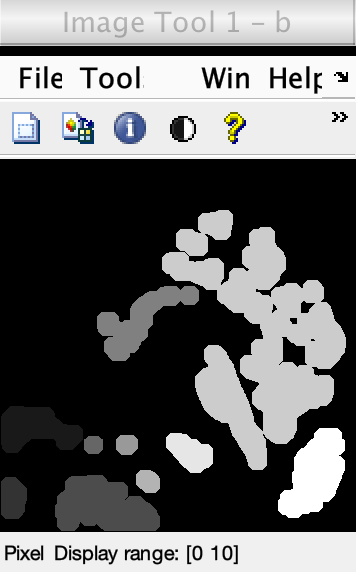


clc;
close all;
clear all;
k=imread("/Users/aaditya/Desktop/fig5.png");
k=rgb2gray(k);

subplot(221);imshow(k,[]);title('gray')
k1=im2bw(k,graythresh(k));
subplot(222);imshow(k1);title('thresholded image')
SE=strel('disk',10);
k2=imopen(k1,SE); 
subplot(223);imshow(k2);title('connected components')
b=bwlabel(k2);
imtool(b,[]);

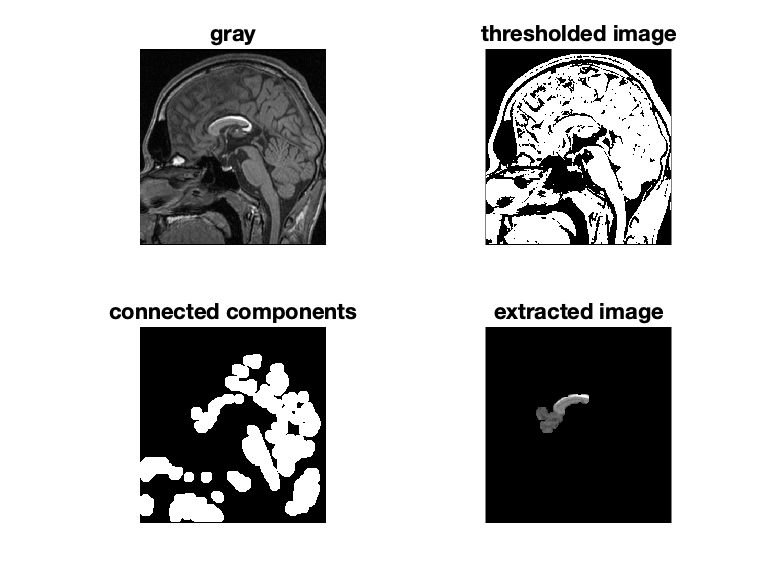

b(b~=5)=0;
subplot(224);
for i =1:375
    for j =1:356
        if((b(i,j))==0)
            k(i,j)=0;
        else
            k(i,j)=k(i,j);
    end
    end
end
imshow(k,[]);title('extracted image')